clear all;
%Dateien laden und in eine Variable speichern
dateiName = fullfile('.', 'spamData.mat');
T = load(dateiName)

T = struct with fields:
     testData: [1393×57 double]
      testLbl: [1393×1 categorical]
    trainData: [3208×57 double]
     trainLbl: [3208×1 categorical]
          url: 'https://archive.ics.uci.edu/ml/datasets/Spambase'


%Datensatz zufällig einteilen
r = randperm(3208);

nvTrainData = T.trainData(r(1:2245), :);
nvLblData = T.trainLbl(r(1:2245), :);
vTrainData = T.trainData(r(2246:end), :);
vLblData = T.trainLbl(r(2246:end), :);


%Trainieren des Models
bwTest = [0.01:0.01:0.1, 0.12:0.02:0.3, 0.35:0.05:1];

bwTest =     0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1200    0.1400    0.1600    0.1800    0.2000    0.2200    0.2400    0.2600    0.2800    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000


arrayIndex = 1;

trainErr = zeros(length(bwTest), 1);
valErr = zeros(length(bwTest), 1);
testErr = zeros(length(bwTest), 1);

tic;
for ii = 1:length(bwTest)
mdl = fitcnb(gpuArray(nvTrainData), nvLblData, 'DistributionNames', 'kernel', 'Width', bwTest(ii)); 
%Traniningsfehler
trainLblPred = predict(mdl, nvTrainData); 
trainErr(arrayIndex) = sum(trainLblPred ~= nvLblData) / length(nvLblData);

%Validierungsfehler
valLblPred = predict(mdl, vTrainData);
valErr(arrayIndex) = sum(valLblPred ~= vLblData) / length(vLblData);

%Testfehler
testLblPred = predict(mdl, T.testData);
testErr(arrayIndex) = sum(testLblPred ~= T.testLbl) / length(T.testLbl);
arrayIndex = arrayIndex + 1;
end
computationTime = toc

computationTime = 126.7376

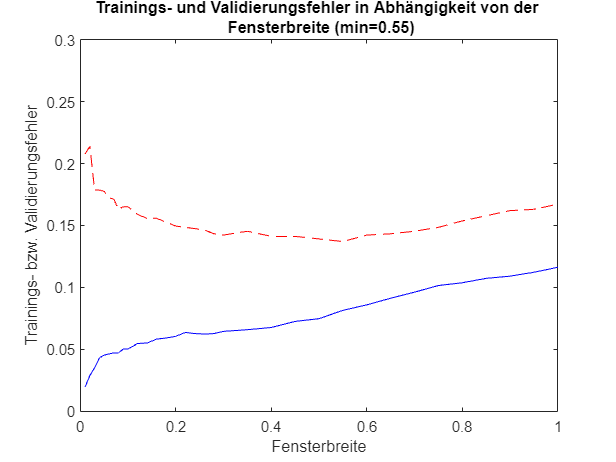


%Trainings- und Validierungsfehler plotten
plot(bwTest, trainErr, 'blue');
ylim([0 0.3])
xlabel(sprintf("Fensterbreite"))
ylabel(sprintf("Trainings- bzw. Validierungsfehler"))
title(sprintf("Trainings- und Validierungsfehler in Abhängigkeit von der \n Fensterbreite (min=%.2f)", min(bwTest(valErr == min(valErr)))))
hold on;
plot(bwTest, valErr, '--', 'Color', 'red');
hold off;

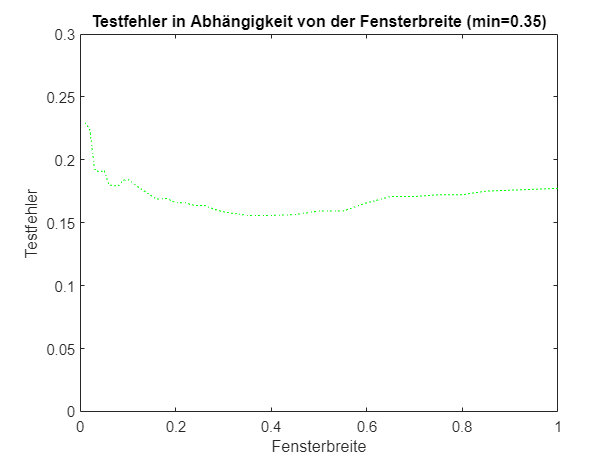

%Testfehler zur Überprüfung plotten
plot(bwTest, testErr, ':', 'Color', 'green');
title(sprintf("Testfehler in Abhängigkeit von der Fensterbreite (min=%.2f)", min(bwTest(testErr == min(testErr)))))
ylim([0 0.3])
xlabel(sprintf("Fensterbreite"))
ylabel(sprintf("Testfehler"))

%Trainings-, Validierungs- und Testdaten normieren

mTrain = mean(nvTrainData);
mVal = mean(vTrainData);
mTest = mean(T.testData);

sTrain = std(nvTrainData);
sVal = std(vTrainData);
sTest = std(T.testData);

normNVTrainData = (nvTrainData-mTrain)./sTrain;
normVTrainData = (vTrainData-mVal)./sVal;
normTestData = (T.testData-mTest)./sTest;

%Analyse wiederholen
normTrainErr = zeros(length(bwTest), 1);
normValErr = zeros(length(bwTest), 1);
normTestErr = zeros(length(bwTest), 1);
arrayIndex = 1;
tic;
for ii = 1:length(bwTest)
mdl = fitcnb(gpuArray(normNVTrainData), nvLblData, 'DistributionNames', 'kernel', 'Width', bwTest(ii)); 
%Traniningsfehler
trainLblPred = predict(mdl, normNVTrainData); 
normTrainErr(arrayIndex) = sum(trainLblPred ~= nvLblData) / length(nvLblData);

%Validierungsfehler
valLblPred = predict(mdl, normVTrainData);
normValErr(arrayIndex) = sum(valLblPred ~= vLblData) / length(vLblData);

%Testfehler
testLblPred = predict(mdl, normTestData);
normTestErr(arrayIndex) = sum(testLblPred ~= T.testLbl) / length(T.testLbl);
arrayIndex = arrayIndex + 1;
end
computationTimeNorm = toc

computationTimeNorm = 91.0109

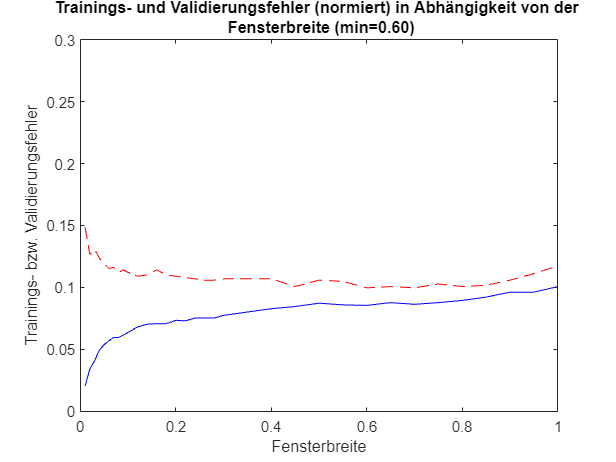

%Trainings- und Validierungsfehler plotten (normiert)
plot(bwTest, normTrainErr, 'blue');
ylim([0 0.3])
xlabel(sprintf("Fensterbreite"))
ylabel(sprintf("Trainings- bzw. Validierungsfehler"))
title(sprintf("Trainings- und Validierungsfehler (normiert) in Abhängigkeit von der \n Fensterbreite (min=%.2f)", min(bwTest(normValErr == min(normValErr)))))
hold on;
plot(bwTest, normValErr, '--', 'Color', 'red');
hold off;

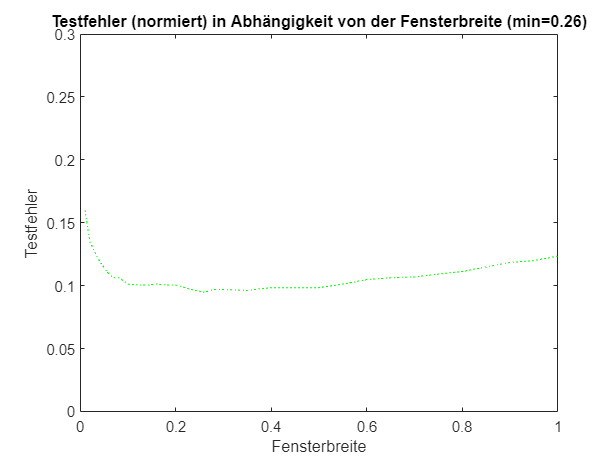

%Testfehler zur Überprüfung plotten
plot(bwTest, normTestErr, ':', 'Color', 'green');
title(sprintf("Testfehler (normiert) in Abhängigkeit von der Fensterbreite (min=%.2f)", min(bwTest(normTestErr == min(normTestErr)))))
ylim([0 0.3])
xlabel(sprintf("Fensterbreite"))
ylabel(sprintf("Testfehler"))

%Wiederholung von Versuchteil b) mit kNN
nearestNeighbors = [1:10, 12:2:30, 35:5:100];
arrayIndex = 1;

knnTrainErr = zeros(length(nearestNeighbors), 1);
knnValErr = zeros(length(nearestNeighbors), 1);
knnTestErr = zeros(length(nearestNeighbors), 1);
tic;
for ii = 1:length(nearestNeighbors)
mdl = fitcknn(gpuArray(nvTrainData), nvLblData, 'NumNeighbors', nearestNeighbors(ii)); 
%Traniningsfehler
trainLblPred = predict(mdl, nvTrainData); 
knnTrainErr(arrayIndex) = sum(trainLblPred ~= nvLblData) / length(nvLblData);

%Validierungsfehler
valLblPred = predict(mdl, vTrainData);
knnValErr(arrayIndex) = sum(valLblPred ~= vLblData) / length(vLblData);

%Testfehler
testLblPred = predict(mdl, T.testData);
knnTestErr(arrayIndex) = sum(testLblPred ~= T.testLbl) / length(T.testLbl);
arrayIndex = arrayIndex + 1;
end
computationTimeKnn = toc

computationTimeKnn = 4.0664

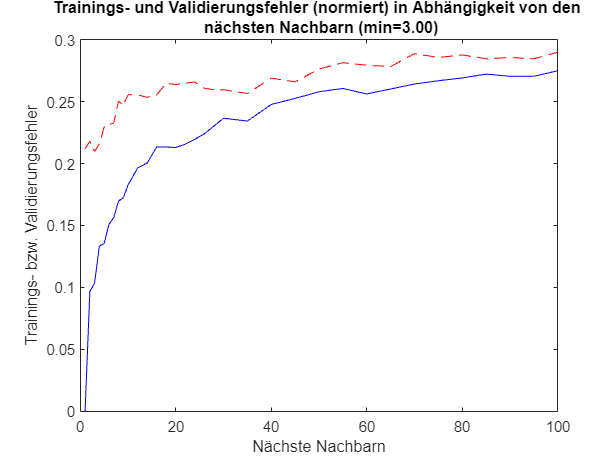

plot(nearestNeighbors, knnTrainErr, 'blue');
ylim([0 0.3])
xlabel(sprintf("Nächste Nachbarn"))
ylabel(sprintf("Trainings- bzw. Validierungsfehler"))
title(sprintf("Trainings- und Validierungsfehler in Abhängigkeit von den \n nächsten Nachbarn (min=%.2f)", (nearestNeighbors(knnValErr == min(knnValErr)))))
hold on;
plot(nearestNeighbors, knnValErr, '--', 'Color', 'red');
hold off;

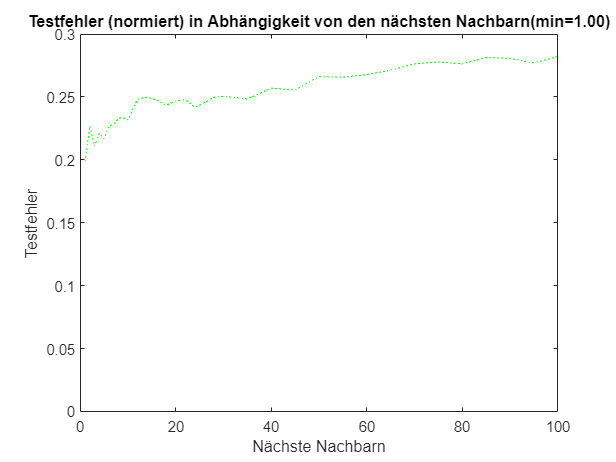

%Testfehler zur Überprüfung plotten
plot(nearestNeighbors, knnTestErr, ':', 'Color', 'green');
title(sprintf("Testfehler in Abhängigkeit von den nächsten Nachbarn(min=%.2f)", (nearestNeighbors(knnTestErr == min(knnTestErr)))))
ylim([0 0.3])
xlabel(sprintf("Nächste Nachbarn"))
ylabel(sprintf("Testfehler"))

%Analyse mit KNN wiederholen mit normierten Daten
arrayIndex = 1;

normknnTrainErr = zeros(length(nearestNeighbors), 1);
normknnValErr = zeros(length(nearestNeighbors), 1);
normknnTestErr = zeros(length(nearestNeighbors), 1);
tic;
for ii = 1:length(nearestNeighbors)
mdl = fitcknn(gpuArray(normNVTrainData), nvLblData, 'NumNeighbors', nearestNeighbors(ii)); 
%Traniningsfehler
trainLblPred = predict(mdl, normNVTrainData); 
normknnTrainErr(arrayIndex) = sum(trainLblPred ~= nvLblData) / length(nvLblData);

%Validierungsfehler
valLblPred = predict(mdl, normVTrainData);
normknnValErr(arrayIndex) = sum(valLblPred ~= vLblData) / length(vLblData);

%Testfehler
testLblPred = predict(mdl, normTestData);
normknnTestErr(arrayIndex) = sum(testLblPred ~= T.testLbl) / length(T.testLbl);
arrayIndex = arrayIndex + 1;
end
computationTimeKnn = toc

computationTimeKnn = 1.8011

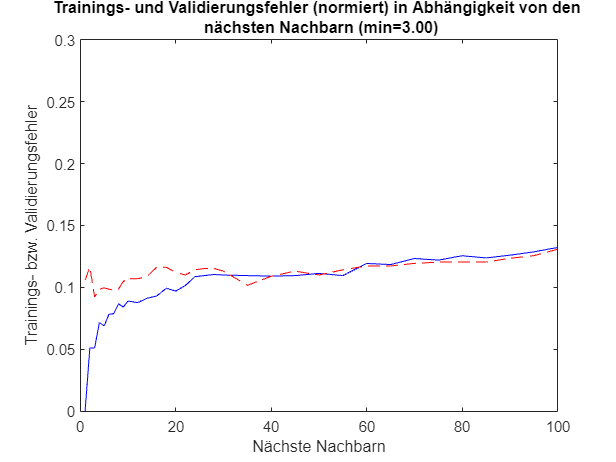

plot(nearestNeighbors, normknnTrainErr, 'blue');
ylim([0 0.3])
xlabel(sprintf("Nächste Nachbarn"))
ylabel(sprintf("Trainings- bzw. Validierungsfehler"))
title(sprintf("Trainings- und Validierungsfehler (normiert) in Abhängigkeit von den \n nächsten Nachbarn (min=%.2f)", (nearestNeighbors(normknnValErr == min(normknnValErr)))))
hold on;
plot(nearestNeighbors, normknnValErr, '--', 'Color', 'red');
hold off;

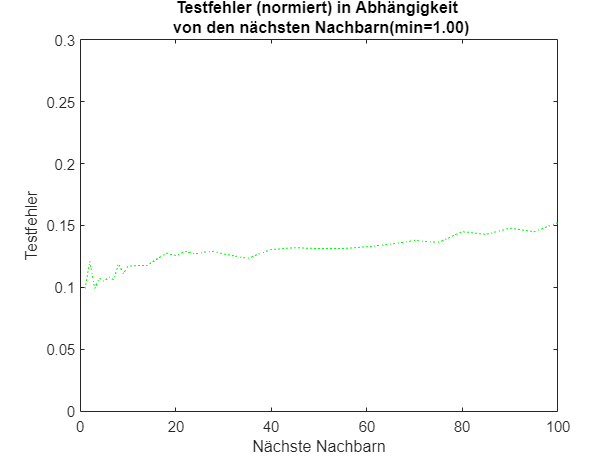

%Testfehler zur Überprüfung plotten
plot(nearestNeighbors, normknnTestErr, ':', 'Color', 'green');
title(sprintf("Testfehler (normiert) in Abhängigkeit \n von den nächsten Nachbarn(min=%.2f)", min(nearestNeighbors(normknnTestErr == min(normknnTestErr)))))
ylim([0 0.3])
xlabel(sprintf("Nächste Nachbarn"))
ylabel(sprintf("Testfehler"))